# Simulate ABW Z-call sigmoid and estimate signal's covariance matrix

In this code: 

- First, the Z-call sigmoid is simulated based on FX. Socheleau 2015 JASA paper.

- then, the covariance matrix of the signal is evaluated as a first part of the SMF application

clearvars
close all
clc

addpath ../Functions

Choose if the output is saved or not

Save = 'On'; 
disp(['Save is: ' Save])

Save is: On


## Sigmoid parameters

Here, for ABW call detection, the parametric model described in (Socheleau, 2015) is used. It is based on the complex form of an acoustic signal $s(n) = a(n)e^{j\varphi(n)}$, with $a(n)$ the time-varying amplitude and $\varphi(n)$ the time-varying phase. From the definition of the instantaneous frequency and its parametric expression as a fuction of the (continuous) time


$$f(t)=f_c+\frac{1}{2\pi}\frac{\text{d}\varphi(t)}{\text{d}t} = f_c+L+\frac{U-L}{1+e^{\alpha(t-M)}},$$


it is possible to derive the expression of the time-varying phase $\varphi(n)$, where $n$,denotes the discrete time, as


$$\varphi(n) = 2\pi\left(L\frac{n}{f_s}+\frac{U-L}{\alpha}\ln\left(\frac{1+e^{-\alpha M}}{1+e^{\alpha(\frac{n}{f_s}-M)}}\right)\right)+\varphi_0,$$


where $f_c = 22.6$ Hz is the central frequency in the $[15-30]$Hz bandwidth, $L$ and $U$are respectively linked to the lower and upper asymptotes of the Z-call, $M$ represents the time shift and $\alpha$ the grow rate. The amplitude $a(n)$, is set to vary in accordance with the energetic difference between unit A and C. 

### Definition of the different constants

fs = 100 ; % (Hz) sampling frequency

Tz = 20 ; % (s) duration of an ABW call
tz = 0:1/fs:Tz; % time axis
N = length(tz); % number of samples

fc = 22.6 ;  % (Hz) Z-call center frequency
alpha = 1.8; % slope

L = -4.5 ;   % (Hz) Lower assymptote
U = 3.2 ;    % (Hz) Upper asymptote 
M = Tz/2;    % (s) time at half of the slope


## Instantaneous frequency

This section is not mandatory, it can just be used to visualize the result simulated call

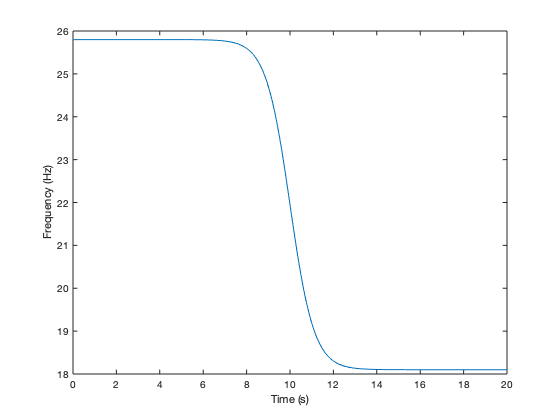

f_whale = zeros(length(L),N);
for i = 1:length(L)
    f_whale(i,:) = fc + L(i) + ((U(i)-L(i))./(1+exp(alpha*(tz-M(i)))));
end

figure
plot(tz,f_whale)
xlabel('Time (s)')
ylabel('Frequency (Hz)')

## Estimation of the time-varying phase

adj = fc - 8.5; % Compared to the Socheleau paper, the sigmoid has to be 
                % shifted in frequency to match the Z-call signal
L = L-adj; % Lower asymptote (Hz)
U = U-adj; % Upper asymptote (Hz)

% Phase calculation
n = 0:N-1; % Sample axis
phase_whale = 2*pi*(L*n/fs + ((U-L)/alpha) * ...
    log((1+exp(-alpha*M))./(1+exp(alpha*(n/fs-M)))));
phase_whale = phase_whale(end:-1:1);    % Reverse in time to have it from high to low frequency

% Temporal signal
s_whale = exp(1j*phase_whale); 
s_whale = real(s_whale/max(abs(s_whale))); 

% Amplitude variation through time
amplitude = [ones(1,round(N/2)-1) ones(1,round(N/2))*0.95];
s_whale = amplitude.*s_whale;
s_whale = s_whale/max(abs(s_whale));

##  Covariance matrix estimation

[covs,vecs] = SMF_sig_preprocess(s_whale);

## Save matrices

switch Save
    case 'On'
        save('../Offline_saved/s_whale.mat', 's_whale','covs','vecs')
        disp('Matrices saved in: Offline_saved/s_whale.mat')
    case 'Off' 
        disp('Matrices not saved')
    otherwise warning('Uknown Save command - matrices not saved')
end

Matrices saved in: Offline_saved/s_whale.mat
